% Species Prediction
files = dir("history_data/*_history.csv")

files = 4×1 struct array with fields:
    name
    folder
    date
    bytes
    isdir
    datenum


names = string.empty(length(files), 0);
for i = 1:length(files)
     names(i) = files(i).name;
end
names = names'

names = 4×1 string array
    "characteristic_bolete.h5_history.csv"
    "characteristic_bolete_lowres.h5_history.csv"
    "direct_bolete.h5_history.csv"
    "direct_bolete_lowres.h5_history.csv"


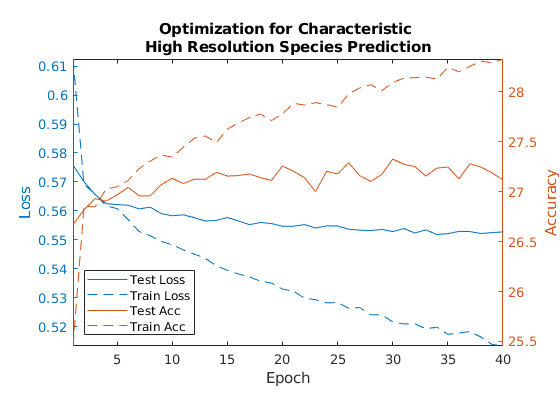

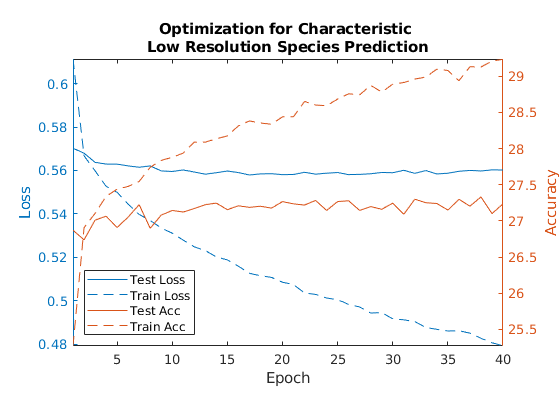

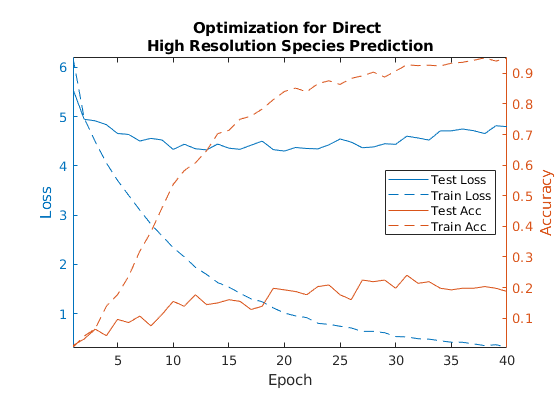

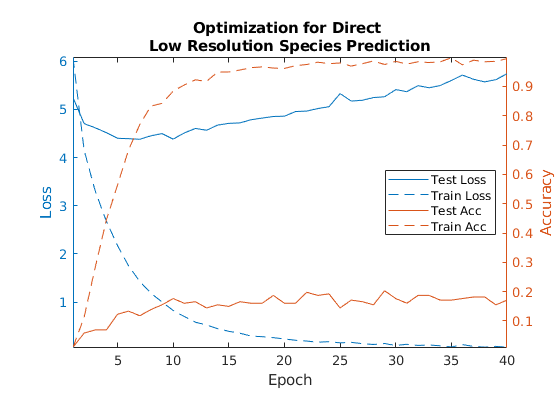


for i= 1:length(names)
    f = names(i);
    t = readtable("history_data/"+f);
    fig = plotCurves(t, title_from_suffix(f));
    saveas(fig, "plots/" + replace(title_from_suffix(f), newline, "") + ".png");
end


% Edibility
files = dir("history_data_ed/*_history.csv")

files = 2×1 struct array with fields:
    name
    folder
    date
    bytes
    isdir
    datenum


ednames = string.empty(length(files), 0);
for i = 1:length(files)
     ednames(i) = files(i).name;
end
ednames = ednames'

ednames = 2×1 string array
    "direct_bolete.h5_history.csv"
    "direct_bolete_lowres.h5_history.csv"


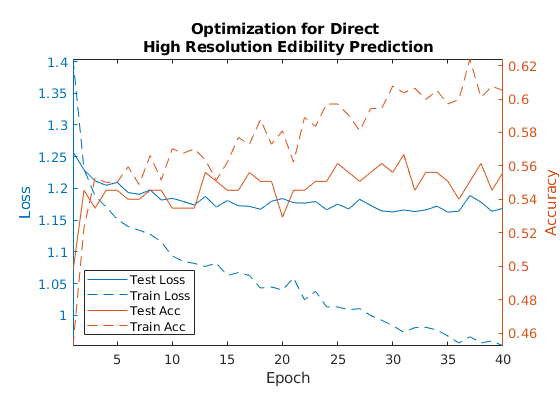

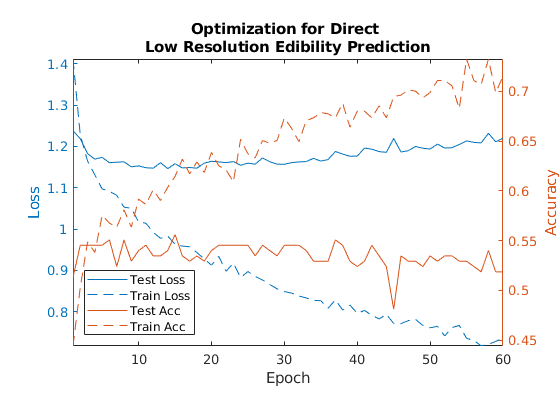

for i= 1:length(ednames)
    f = ednames(i);
    t = readtable("history_data_ed/"+f);
    fig = plotCurves(t, title_from_suffix("history_data_ed/"+f));
    saveas(fig, "plots/" + replace(title_from_suffix("history_data_ed/"+f), newline, "") + ".png");
end

function fig = plotCurves(t, name)
    fig = figure();
%     fig = figure( "Units","normalized", "Position",[0,0,0.4,0.25]);
    yyaxis left
    plotCurve(t.train_loss, t.val_loss, "Loss");
    hold on
    yyaxis right
    plotCurve(t.train_acc, t.val_acc, "Accuracy");
    hold off
    if contains(name, "direct", "IgnoreCase", true) && ~contains(name, "edibility", "IgnoreCase", true)
        loc = "east";
    else
        loc = "southwest";
    end
    
    legend(["Test Loss","Train Loss",...
        "Test Acc","Train Acc"], "Location",loc)
    title(name)
    pbaspect([1.5,1,1])
    axis tight
end
function plotCurve(train, val, type)
    plot(val)
    hold on
    plot(train)
    hold off
    ylabel(type)
    xlabel("Epoch")
end
function tit = title_from_suffix(suffix)
    tit = "Optimization for ";
    suffix = string(suffix);
    if contains(suffix, "direct")
        tit = tit + "Direct ";
    else
        tit = tit + "Characteristic ";
    end
    tit = tit + newline;
    if contains(suffix, "_bolete.h5")
        tit = tit + "High Resolution";
    else
        tit = tit + "Low Resolution";
    end
    if contains(suffix, "_ed")
        tit = tit + " Edibility Prediction";
    else
        tit = tit + " Species Prediction";
    end
end